# DISPOSITIVO 2

- Ricezione del messaggio inviato da dispositivo 1

- Classificazione della comunicazione e cambio di code rate e modulation order

- Invio dei nuovi parametri di trasmissione

- Se viene ricevuto un keep alive, invia gli ultimi parametri inviati.

[OFDMParams,dataParams, GeneralParam] = helperSetParameters();
endureCommunication = 1;

### RICEZIONE

## Establishing connection to hardware. This process can take several seconds.



BER = 0 

Sync symbol found.
Estimating carrier frequency offset ...
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 
.
BER = 5.000000e-01 

Receiver camped.

BER = 5.000000e-01 
Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -1.074154e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed
Received data in frame 10: Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello worn4! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hello world! Hel

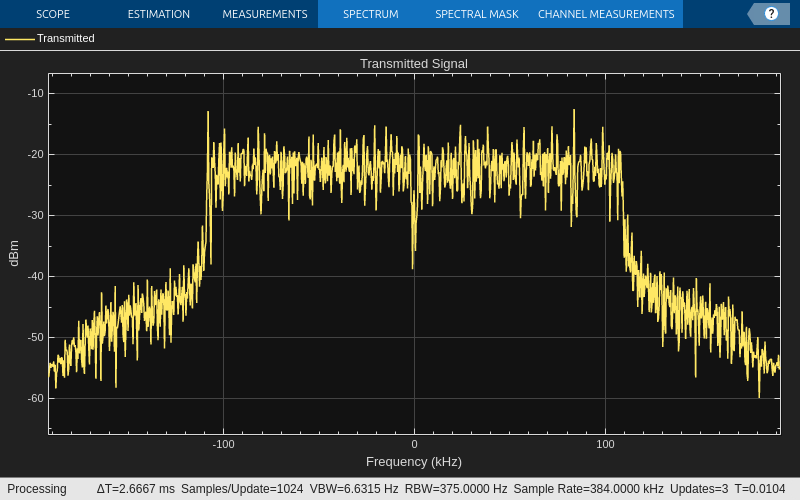

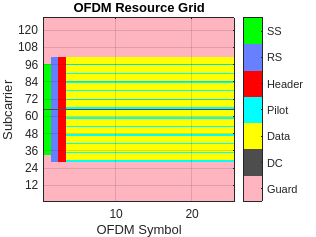

## Establishing connection to hardware. This process can take several seconds.


Error using matlabshared.libiio.base/cstatusid
Failed to create context for uri: usb:1.7.5 
The address is not available. Make sure the device is connected and try again.

Error in matlabshared.libiio.base/getContext

Error in comm.libiio.AD9361.base_control/getContext

Error in matlabshared.libiio.base/setupImpl

Error in comm.libiio.AD9361.base_control/setupImpl

Error in comm.libiio.AD9361.base/setupImpl

Error in comm.libiio.AD9361.tx_control/setupImpl

Error in comm.libiio.AD9361.tx/setupImpl

Error in comm.plutoradio.tx/setupImpl

Error in comm.SDRTxPluto/setupImpl

Error in helperRadioTx (

while endureCommunication
    [rxFlag, params] = helperReceiverModule(GeneralParam, OFDMParams, dataParams);
    if ~rxFlag
        endureCommunication = 0;
    else
        GeneralParam.message = params;
        helperTrasmissionModule(GeneralParam,OFDMParams, dataParams);
    end
end

fprintf('Comunicazione terminata\nNon è stato ricevuto nulla!\n');